figure
for i =1:9
    subplot(8,3,i)
end
subplot(8,3,[10:18])
subplot(8,3,[19:21])
subplot(8,3,[22:24])

figure
subplot(10,3,10:18)
plot_areaerrorbar(psth_alum_aud,optionsAl)
hold on
plot_areaerrorbar(psth_mut_aud,optionsMu)
hold on
plot_areaerrorbar(psth_non_aud,optionsNo)
title('PSTH')


subplot(10,3,[19:24])
plot(predTimeVector,aluminumPredicted,'Color',FVB103_849.experiment.color.Aluminum)
hold on
plot(predTimeVector,mutedPredicted,'Color',FVB103_849.experiment.color.Muted)
plot(predTimeVector,nonPredicted,'Color',FVB103_849.experiment.color.noObject)
ylim([0 0.15])



subplot(10,3,[25:30])
plot(epTimeVector,aluminumReal,'Color',FVB103_849.experiment.color.Aluminum)
hold on
plot(epTimeVector,mutedReal,'Color',FVB103_849.experiment.color.Muted)
plot(epTimeVector,nonReal,'Color',FVB103_849.experiment.color.noObject)
ylim([0 0.15])

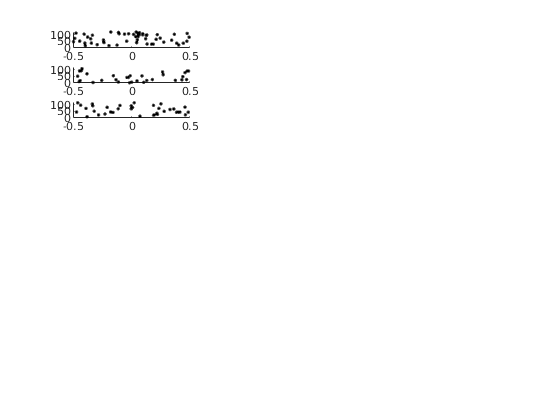

figure;
subplot(10,3,1)
createRaster(FVB103_757.experiment.sound_events.aluminumEvents,FVB103_757.experiment.Units.mua.times(12,:),1);
ylim([0 120])
subplot(10,3,4)
ylim([0 120])
createRaster(FVB103_757.experiment.sound_events.mutedEvents,FVB103_757.experiment.Units.mua.times(12,:),1);
subplot(10,3,7)
ylim([0 120])
createRaster(FVB103_757.experiment.sound_events.nonEvents,FVB103_757.experiment.Units.mua.times(12,:),1);

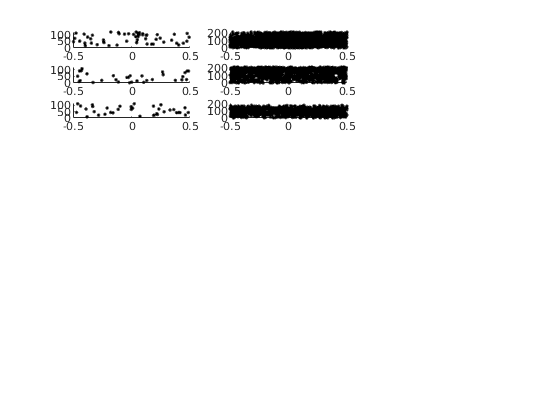

subplot(10,3,2)
createRaster(FVB103_849.experiment.sound_events.aluminumEvents,FVB103_849.experiment.Units.good.times(6,:),1);
ylim([0 220])
subplot(10,3,5)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.mutedEvents,FVB103_849.experiment.Units.good.times(6,:),1);
subplot(10,3,8)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.nonEvents,FVB103_849.experiment.Units.good.times(6,:),1);

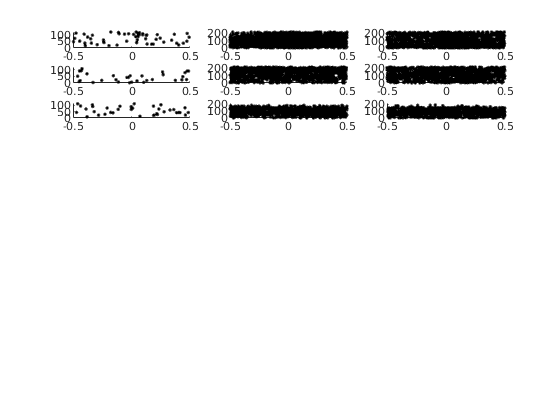

subplot(10,3,3)
createRaster(FVB103_849.experiment.sound_events.aluminumEvents,FVB103_849.experiment.Units.mua.times(1,:),1);
ylim([0 220])
subplot(10,3,6)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.mutedEvents,FVB103_849.experiment.Units.mua.times(1,:),1);
subplot(10,3,9)
ylim([0 220])
createRaster(FVB103_849.experiment.sound_events.nonEvents,FVB103_849.experiment.Units.mua.times(1,:),1);


for i = 1: length(psth_alum_aud)
    figure;
    plot(psth_alum_aud(41,:))
    title(['number ',num2str(i)])
end

for i = 1:42
    figure;
    plot(psth_mut_aud(i,:))
    title(['number ',num2str(i)])
end
